## Initialise class and connect to simulator

    %% Make sure the Simulation subfolder is added to your workspace path %%
    clear all
    
    %use sync flag to operate in syncronous mode 
    %requires manual call to stepSim() function to make sim take
    %one time step
    sync = false;
    dobot_sim = coppeliaRobot('Dobot');

Creating robot
Connecting to Simulator
Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)
Connected to remote API server
Successfully connected to API server 


    dobot_sim.startSim(sync);
    

## Move joints

    % angle of each joint
    target = [37.9 56.2 -35 20 0];
    
    dobot_sim.setJointPositions(target);
    
    % What if the robot hasn't reached the target before the next command?
    dobot_sim.getJointPositions();
    

## Get the image from the vision sensor (eye in hand)

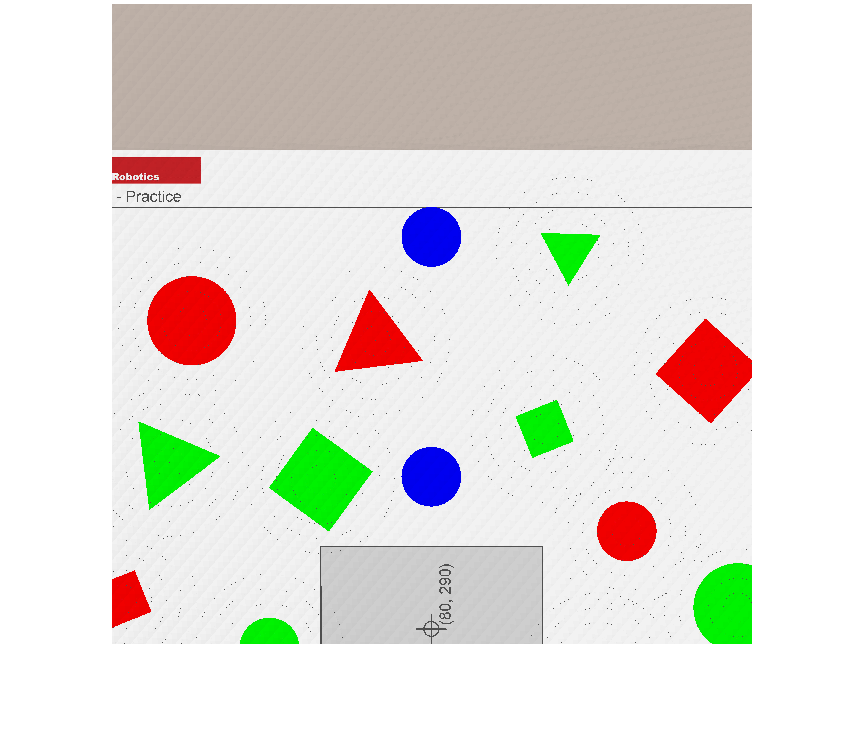

    image = dobot_sim.getImage();
    imshow(image);

## Set the suction cup to grab

    dobot_sim.setSuctionCup(true);
    

## Advanced - Velocity control

    
    qdot = [0, 0, 0.1, 0.1, 0]

qdot =          0         0    0.1000    0.1000         0


    dobot_sim.setJointVelocities(qdot)
    qdot_actual = dobot_sim.getJointVelocities()

qdot_actual = 1×5 single row vector
    2.8192   22.3579         0   -0.0008   -0.0030
